# Midterm Question 3

**Author: Keith Chester**

**E-mail: kchester@wpi.edu**

## Methods

We will be looking at solving the Jacobian for the following robot:

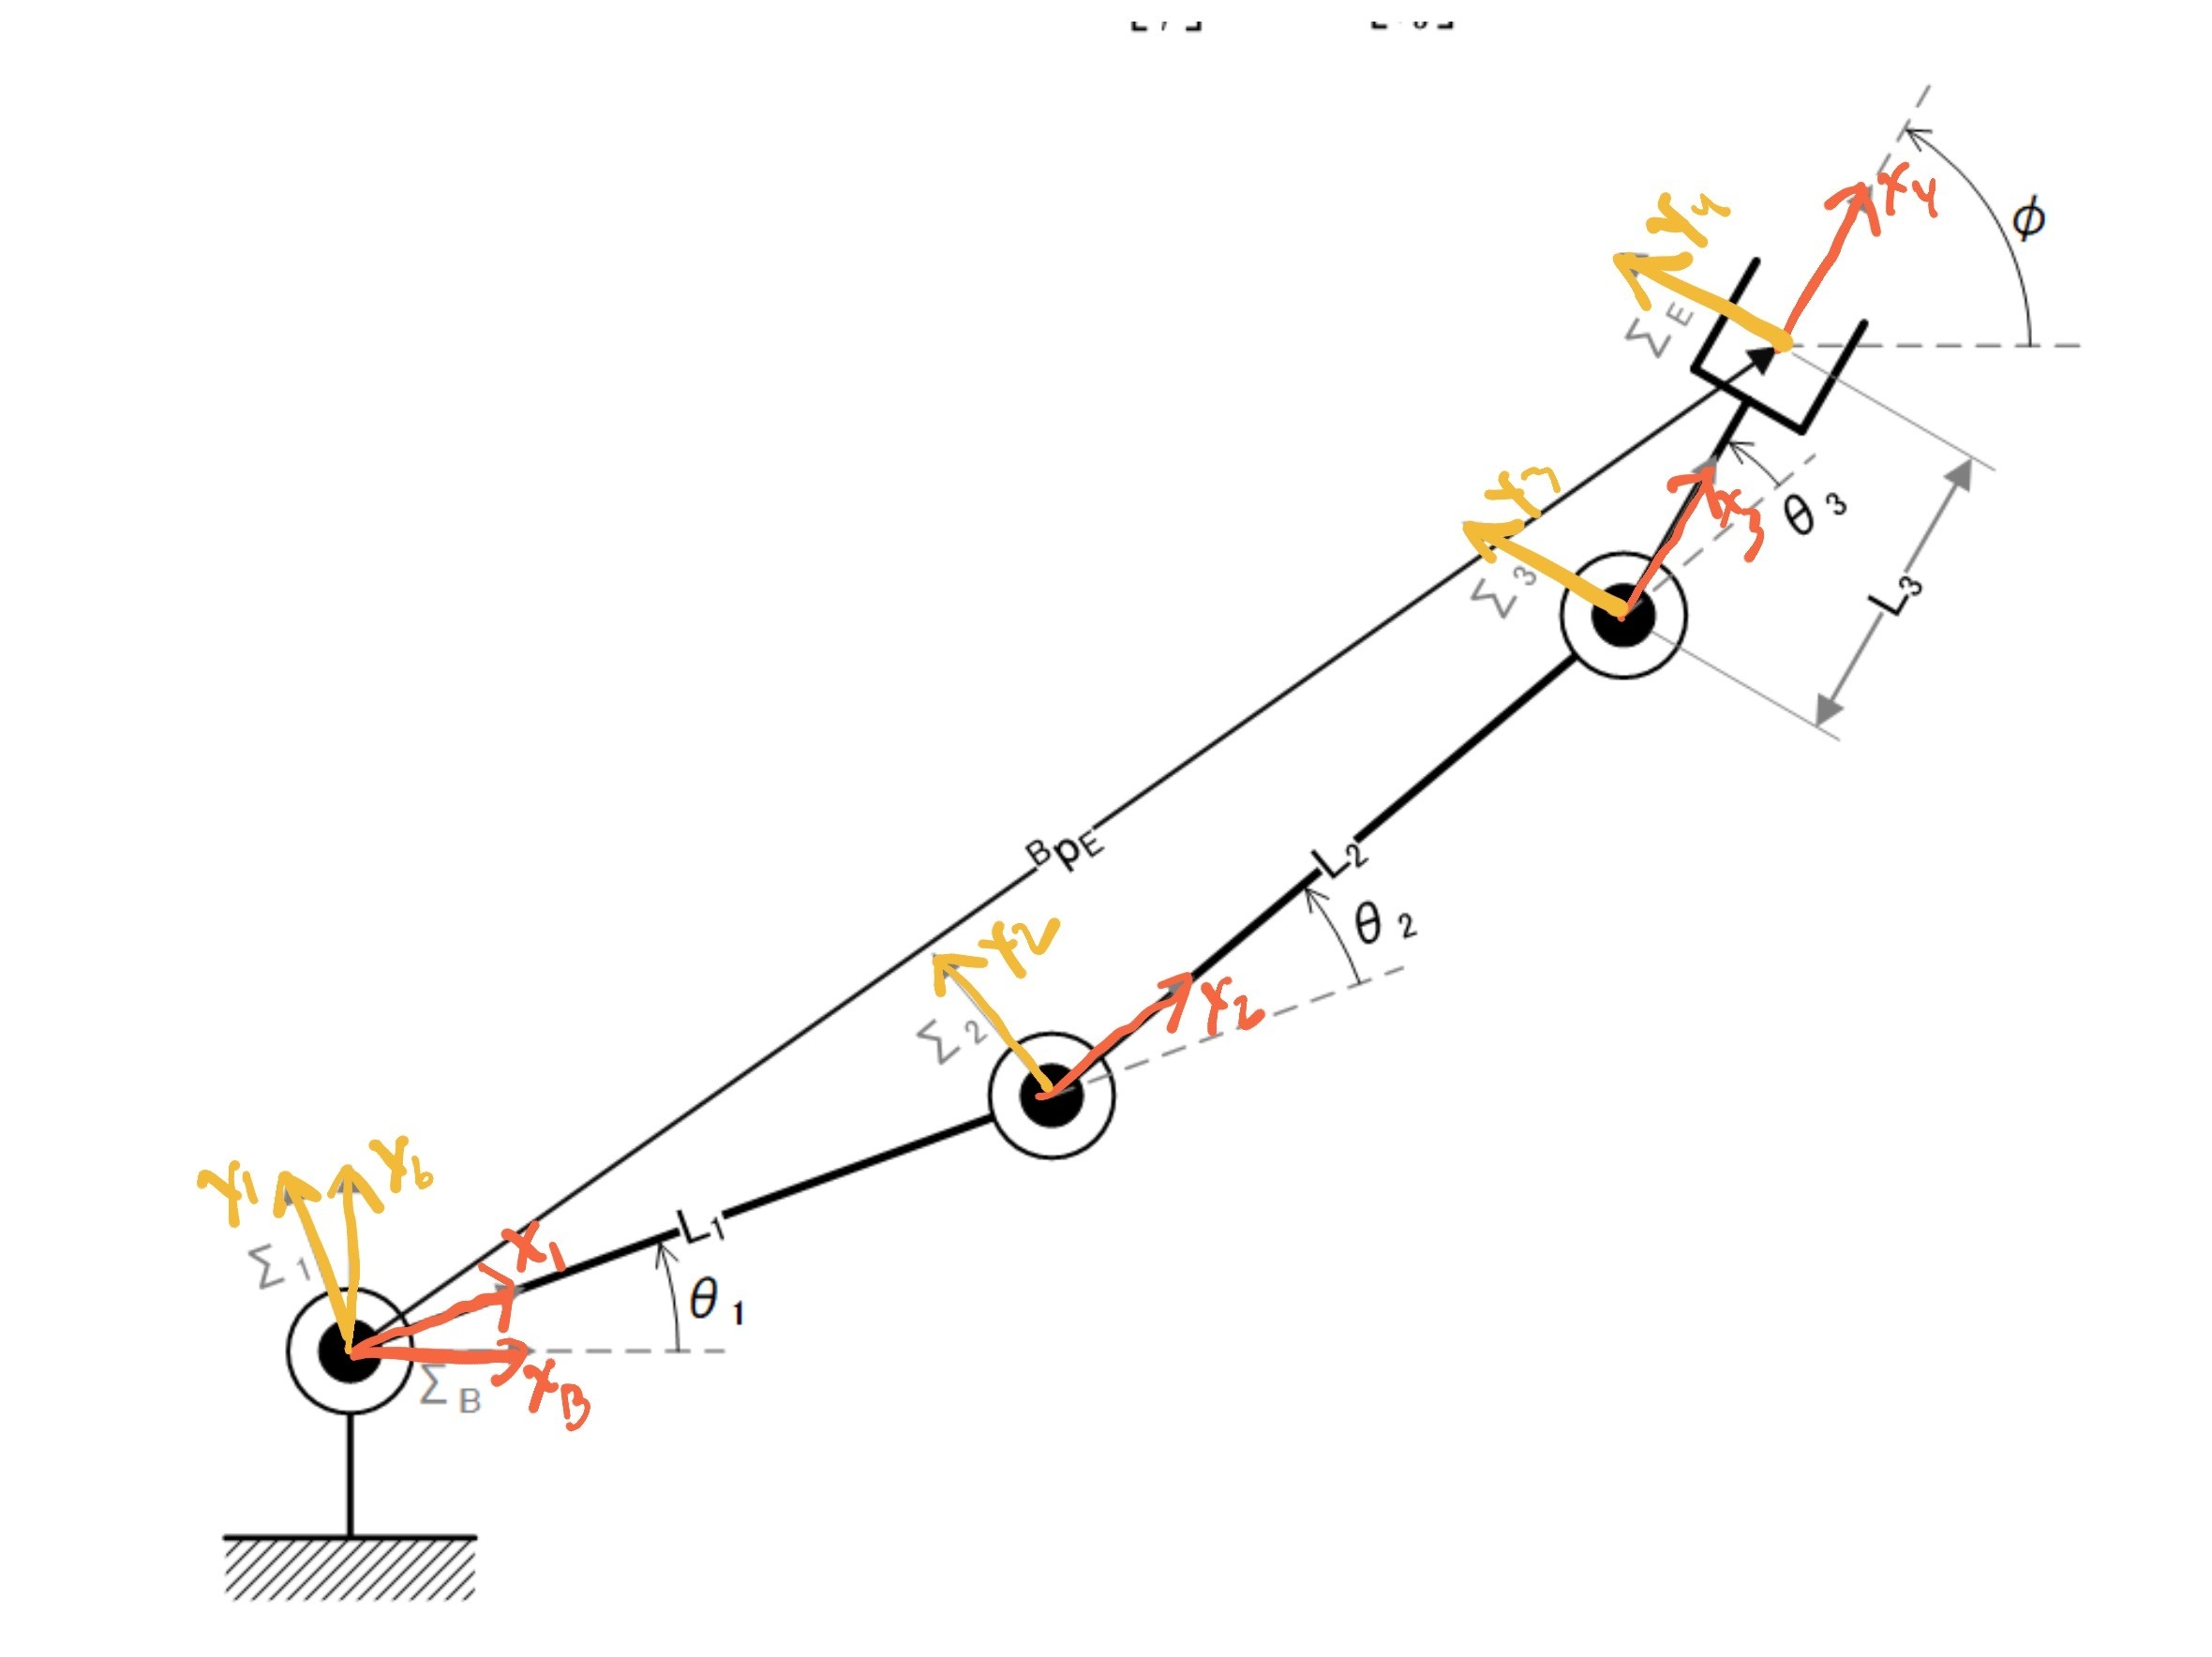

To do this, we will first make use of the axis, which we'll label ast to follow DH convention, and make a DH table for them. In this regard, we consider the direction of the next joint to be the X axis, the Z axis to be coming "out of" the page towards the reader, and the y axis as the right hand fulfillment of that. We also create symbolic values to work our algebra with when trying to solve for the Jacobian. We will label the rotations of each joint as $\phi ,\theta ,\mathrm{and}\;\psi$, respectively.

syms phi theta psi l1 l2 l3

dh_table = {
    [phi     0   l1      0],
    [theta   0   l2      0 ],
    [psi     0   l3      0 ],
}

dh_table = 3×1 cell array
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}


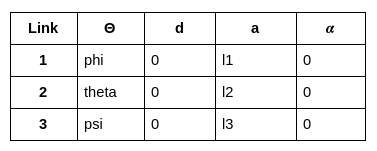

Using the DH table, we can generate transformation matricies for each link. We can see them here:

A1 = transform_from_dh_row(dh_table, 1, true)

$$A1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & l_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0 & l_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = transform_from_dh_row(dh_table, 2, true)

$$A2 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & l_{2}\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & l_{2}\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = transform_from_dh_row(dh_table, 3, true)

$$A3 = \left(\begin{array}{cccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0 & l_{3}\,\cos\left(\psi \right)\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0 & l_{3}\,\sin\left(\psi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

We need, however, to know the transformation matricies all relative to the base 0 frame. To find that, we must multiply through to create each transformaton matrix.

H_0_1 = A1

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & l_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0 & l_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_2 = simplify(A1*A2)

$$H\_0\_2 = \left(\begin{array}{cccc} \cos\left(\varphi +\theta \right) & -\sin\left(\varphi +\theta \right) & 0 & l_{2}\,\cos\left(\varphi +\theta \right)+l_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi +\theta \right) & \cos\left(\varphi +\theta \right) & 0 & l_{2}\,\sin\left(\varphi +\theta \right)+l_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_3 = simplify(A1*A2*A3)

$$H\_0\_3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & l_{2}\,\cos\left(\varphi +\theta \right)+l_{1}\,\cos\left(\varphi \right)+l_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & l_{2}\,\sin\left(\varphi +\theta \right)+l_{1}\,\sin\left(\varphi \right)+l_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\varphi +\psi +\theta \right)\\ \sigma_{2}=\cos\left(\varphi +\psi +\theta \right) \end{array}$$

Thus our transformation matricies are


$$H_1^0 =$$

$$\left(\begin{array}{cccc}
\mathrm{cos}\left(\phi \right) & -\mathrm{sin}\left(\phi \right) & 0 & l_1 \,\mathrm{cos}\left(\phi \right)\\
\mathrm{sin}\left(\phi \right) & \mathrm{cos}\left(\phi \right) & 0 & l_1 \,\mathrm{sin}\left(\phi \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$$



$$\begin{array}{l}
H_2^0 =\left(\begin{array}{cccc}
\mathrm{cos}\left(\phi +\theta \right) & -\mathrm{sin}\left(\phi +\theta \right) & 0 & l_2 \,\mathrm{cos}\left(\phi +\theta \right)+l_1 \,\mathrm{cos}\left(\phi \right)\\
\mathrm{sin}\left(\phi +\theta \right) & \mathrm{cos}\left(\phi +\theta \right) & 0 & l_2 \,\mathrm{sin}\left(\phi +\theta \right)+l_1 \,\mathrm{sin}\left(\phi \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)\\
H_3^0 =\begin{array}{l}
\left(\begin{array}{cccc}
\sigma_2  & -\sigma_1  & 0 & l_2 \,\mathrm{cos}\left(\phi +\theta \right)+l_1 \,\mathrm{cos}\left(\phi \right)+l_3 \,\sigma_2 \\
\sigma_1  & \sigma_2  & 0 & l_2 \,\mathrm{sin}\left(\phi +\theta \right)+l_1 \,\mathrm{sin}\left(\phi \right)+l_3 \,\sigma_1 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\;\;\sigma_1 =\mathrm{sin}\left(\phi +\psi +\theta \right)\\
\mathrm{}\\
\;\;\sigma_2 =\mathrm{cos}\left(\phi +\psi +\theta \right)
\end{array}
\end{array}$$


Now, with these transformations, we can solve the Jacobian. The Jacobian for a revolute link is:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} x\left(o_n -o_{i-1} \right)\\
z_i -1
\end{array}\right\rbrack$$


...and the Jacobian for a prismatic link is:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


...where $z_i$ is the z component of the rotation for the $H_i^0$ transformation for the *i*-th link, and $o_i$ is the coordinate frame origin for the *i*-th frame relative to the *0*th frame. This also happens to be the translation component of the 

Thus the Jacobian for our arm is, from link 1 to 4, respectively:


$$J=\left\lbrack \begin{array}{ccc}
z_o x\left(o_3 -o_0 \right) & z_1 x\left(o_3 -o_1 \right) & z_2 x\left(o_3 -o_2 \right)\\
z_0  & z_1  & z_2 
\end{array}\right\rbrack$$


or, expanded:


$$J=\left\lbrack \begin{array}{ccc}
\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack x\left(\left\lbrack \begin{array}{c}
l_2 \mathrm{cos}\left(\phi +\theta \right)+l_1 \mathrm{cos}\left(\phi \right)+l_3 \mathrm{cos}\left(\phi +\psi +\theta \right)\\
l_2 \mathrm{sin}\left(\phi +\theta \right)+l_1 \mathrm{sin}\left(\phi \right)+l_3 \mathrm{sin}\left(\phi +\psi +\theta \right)\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \right) & \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack x\left(\left\lbrack \begin{array}{c}
l_2 \mathrm{cos}\left(\phi +\theta \right)+l_1 \mathrm{cos}\left(\phi \right)+l_3 \mathrm{cos}\left(\phi +\psi +\theta \right)\\
l_2 \mathrm{sin}\left(\phi +\theta \right)+l_1 \mathrm{sin}\left(\phi \right)+l_3 \mathrm{sin}\left(\phi +\psi +\theta \right)\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
l_1 \mathrm{cos}\left(\phi \right)\\
l_1 \mathrm{sin}\left(\phi \right)\\
0
\end{array}\right\rbrack \right) & \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack x\left(\left\lbrack \begin{array}{c}
l_2 \mathrm{cos}\left(\phi +\theta \right)+l_1 \mathrm{cos}\left(\phi \right)+l_3 \mathrm{cos}\left(\phi +\psi +\theta \right)\\
l_2 \mathrm{sin}\left(\phi +\theta \right)+l_1 \mathrm{sin}\left(\phi \right)+l_3 \mathrm{sin}\left(\phi +\psi +\theta \right)\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
l_2 \mathrm{cos}\left(\phi +\theta \right)+l_1 \mathrm{cos}\left(\phi \right)\\
l_2 \mathrm{sin}\left(\phi +\theta \right)+l_1 \mathrm{sin}\left(\phi \right)\\
0
\end{array}\right\rbrack \right)\\
\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


...which, when simplified, leads to:


$$J=\left\lbrack \begin{array}{ccc}
-l_2 \mathrm{sin}\left(\phi +\theta \right)-l_1 \mathrm{sin}\left(\phi \right)-l_3 \mathrm{sin}\left(\phi +\psi +\theta \right) & -l_2 \mathrm{sin}\left(\phi +\theta \right)-l_3 \mathrm{sin}\left(\phi +\psi +\theta \right) & -l_3 \mathrm{sin}\left(\phi +\psi +\theta \right)\\
l_2 \mathrm{cos}\left(\phi +\theta \right)+l_1 \mathrm{cos}\left(\phi \right)+l_3 \mathrm{cos}\left(\phi +\psi +\theta \right) & l_2 \mathrm{cos}\left(\phi +\theta \right)+l_3 \mathrm{cos}\left(\phi +\psi +\theta \right) & l_3 \mathrm{cos}\left(\phi +\psi +\theta \right)\\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1 & 1 & 1
\end{array}\right\rbrack$$


...with the top half of the matrix representing linear velocity, and he bottom half representing angular velocity.

Once we have the Jacobian of each part, we can then take the $\dot{q}$ matrix, which represents the given velocity of each given joint. We can then solve:

$\xi =J\dot{q}$ where $\xi =\left\lbrack \begin{array}{c}
v_{\mathrm{linear}} \\
v_{\mathrm{angular}} 
\end{array}\right\rbrack$

Here, the linear and angular velocities of the arm, including the tool/actuator, can be read from $\xi$.

## Results

We will define the DH table as above. This time, however, we will allow the setting of key variable values. You will be setting the first three joints, $\phi$,$\theta$, and $\psi$ respectively. Other values will have static values of 1 (for one meter) assigned to them, save $l_1$ which we'll set to 2.5 meters to prevent the arm from constantly going below the ground.

phi = 45;
theta = 15;
psi = 15;

% Static variables
l1 = 2.5;
l2 = 1;
l3 = 1;

dh_table = {
    [phi     0   l1      0],
    [theta   0   l2      0 ],
    [psi     0   l3      0 ],
};

A1 = transform_from_dh_row(dh_table, 1);
A2 = transform_from_dh_row(dh_table, 2);
A3 = transform_from_dh_row(dh_table, 3);
H_0_1 = A1;
H_0_2 = A1*A2;
H_0_3 = A1*A2*A3;

z0 = [0; 0; 1;];
z1 = H_0_1(1:3, 3);
z2 = H_0_2(1:3, 3);
z3 = H_0_3(1:3, 3);

o0 = [0; 0; 0;];
o1 = H_0_1(1:3, 4);
o2 = H_0_2(1:3, 4);
o3 = H_0_3(1:3, 4);

c1 = cross(z0,o3-o0);
c2 = cross(z1,o3-o1);
c3 = cross(z1,o3-o2);

...and, as we recall, the Jacobian is:


$$J=\left\lbrack \begin{array}{ccc}
z_o x\left(o_3 -o_0 \right) & z_1 x\left(o_3 -o_1 \right) & z_2 x\left(o_3 -o_2 \right)\\
z_0  & z_1  & z_2 
\end{array}\right\rbrack$$


...so our resulting Jacobian with values is:

jacobian = [
    c1(1)   c2(1)   c3(1);
    c1(2)   c2(2)   c3(2);
    c1(3)   c2(3)   c3(3);
    z0(1)   z1(1)   z2(1);
    z0(2)   z1(2)   z2(2);
    z0(3)   z1(3)   z2(3);
]

jacobian =    -3.5997   -1.8320   -0.9659
    2.5266    0.7588    0.2588
         0         0         0
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


Looking at the Jacobian above, let's also compute it without going through the process again, and compare results:


$$J=\left\lbrack \begin{array}{ccc}
-l_2 \mathrm{sin}\left(\phi +\theta \right)-l_1 \mathrm{sin}\left(\phi \right)-l_3 \mathrm{sin}\left(\phi +\psi +\theta \right) & -l_2 \mathrm{sin}\left(\phi +\theta \right)-l_3 \mathrm{sin}\left(\phi +\psi +\theta \right) & -l_3 \mathrm{sin}\left(\phi +\psi +\theta \right)\\
l_2 \mathrm{cos}\left(\phi +\theta \right)+l_1 \mathrm{cos}\left(\phi \right)+l_3 \mathrm{cos}\left(\phi +\psi +\theta \right) & l_2 \mathrm{cos}\left(\phi +\theta \right)+l_3 \mathrm{cos}\left(\phi +\psi +\theta \right) & l_3 \mathrm{cos}\left(\phi +\psi +\theta \right)\\
0 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0\\
1 & 1 & 1
\end{array}\right\rbrack$$


analyticalJacobian = [
-l2*sind(phi+theta)-l1*sind(phi)-l3*sind(phi+psi+theta)     -l2*sind(phi+theta)-l3*sind(phi+psi+theta)      -l3*sind(phi+psi+theta);
l2*cosd(phi+theta)+l1*cosd(phi)+l3*cosd(phi+psi+theta)      l2*cosd(phi+theta)+l3*cosd(phi+psi+theta)       l3*cosd(phi+psi+theta)                                      ;
0   0   0;
0   0   0;
1   1   1;
]

analyticalJacobian =    -3.5997   -1.8320   -0.9659
    2.5266    0.7588    0.2588
         0         0         0
         0         0         0
    1.0000    1.0000    1.0000


As we expected, both our analytical approach and our numerical approach to getting the Jacobian from this arm returned exactly the same results. Success!

### Functions and Classes

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then performs *Equation 1*, listed above.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end
